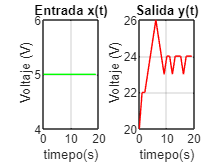

x=[5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 ];
tm=1;
t=[0:tm:20-tm];
y=[20 22 22 23 24 25 26 25 24 23 24 24 23 24 24 24 23 24 24 24];

figure 
subplot(1,2,1)
plot(t,x,'g');
grid on;
hold on;
title('Entrada x(t)')
xlabel( 'timepo(s)')
ylabel(' Voltaje (V)')

subplot(1,2,2)
plot(t,y,'r');
grid on;
hold on;
title('Salida y(t)')
xlabel( 'timepo(s)')
ylabel(' Voltaje (V)')


Gp = tf([7.060228024356327,7.183564356933692,...
5, 314862683587831,1.711075085603947], ...
[1,1,103898178683564, 1.723641041831386,...
0.862197328394244,0, 359312029246585])

Gp =
 
       7.06 s^4 + 7.184 s^3 + 5 s^2 + 3.149e14 s + 1.711
  ------------------------------------------------------------
  s^6 + s^5 + 1.039e14 s^4 + 1.724 s^3 + 0.8622 s^2 + 3.593e14
 
Continuous-time transfer function.




 

Gc=pidtune(Gp,'PID')

Gc =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.0648, Ki = 0.000844, Kd = 1.25
 
Continuous-time PID controller in parallel form.



�